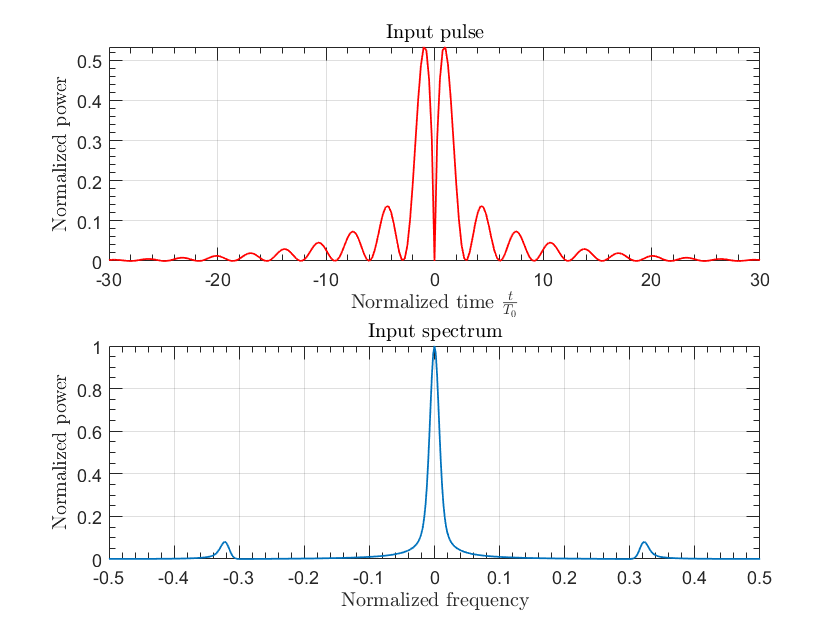

% SSFM code for solving the normalized NLS equation
%Modified version of the code provided by
%G.P. Agrawal for the 6th edition of NLFO book

fiblen = 5;     % fiber length (in units of L_D)
beta2 =-1;      % sign of GVD parameter beta_2
N = 1;          % sign of GVD parameter beta_2


%---set simulation parameters---%
nt = 2048; Tmax = 256;                %FFT points and time window size
step_num = round(20*fiblen*N^2);      %No. z steps
deltaz = fiblen/step_num;             %step size in z
dtau = (2*Tmax)/nt;                   %step size in tau

tns= (-nt/2:nt/2-1);             
tau = tns*dtau;                       %time array
omega = fftshift(tns)*(pi/Tmax);      %omega array
q = 10;
qAiry = 0.333;
w0 = 10;
w0airy = 30;
J = abs(besselj(q,tau));
Jairy = abs(besselj(qAiry,tau));
P0 = 1;

% Create a structure to hold pulse models
pulses = struct();

% Define different pulse shapes
pulses.bessel = sqrt(P0) * exp(-tau.^2 / w0^2) .* J;          % Bessel-Gaussian pulse
pulses.sech = sqrt(P0) * sech(tau);                           % Sech pulse
pulses.gauss = sqrt(P0) * exp(-tau.^2);                       % Gaussian pulse
pulses.airy = sqrt(P0) * exp(-tau.^2 / w0airy^2) .* Jairy;    % Airy pulse

% Now, to select a specific pulse, for example, the Bessel-Gaussian pulse:
pulse_type = 'airy';  % Change this to 'sech', 'gauss', or 'airy' as needed

% Select the pulse based on the chosen type
uu = pulses.(pulse_type);  % This selects the appropriate pulse

%---plot input pulse shape and spectrum---%
temp = fftshift(ifft(uu));            %fourier transform
spect = abs(temp).^2;                 %input spectrum
spect = spect./max(spect);            %normalized spectrum
freq = fftshift(omega)/(2*pi);        %frequency array

figure(1)
subplot(2,1,1)
plot(tau,abs(uu).^2, "LineWidth", 0.9, "Color", [1 0 0])
% legend('$J_5(q, \tau)$', 'Interpreter', 'latex')
xlabel('Normalized time $\frac{t}{T_0}$', "Interpreter", "latex")
ylabel('Normalized power', 'Interpreter',"latex")
title('Input pulse', "Interpreter","latex")
xlim([-30 30])
ylim([0 max(abs(uu).^2)])
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
         'TickLength', [0.02, 0.04], ...
         'LineWidth', 0.5);

subplot(2,1,2)
plot(freq, spect, "LineWidth", 0.9)
title('Input spectrum', "Interpreter","latex")
xlabel('Normalized frequency', "Interpreter", "latex")
ylabel('Normalized power', 'Interpreter',"latex")
xlim([-.5 .5])
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
         'TickLength', [0.02, 0.04], ...
         'LineWidth', 0.5);

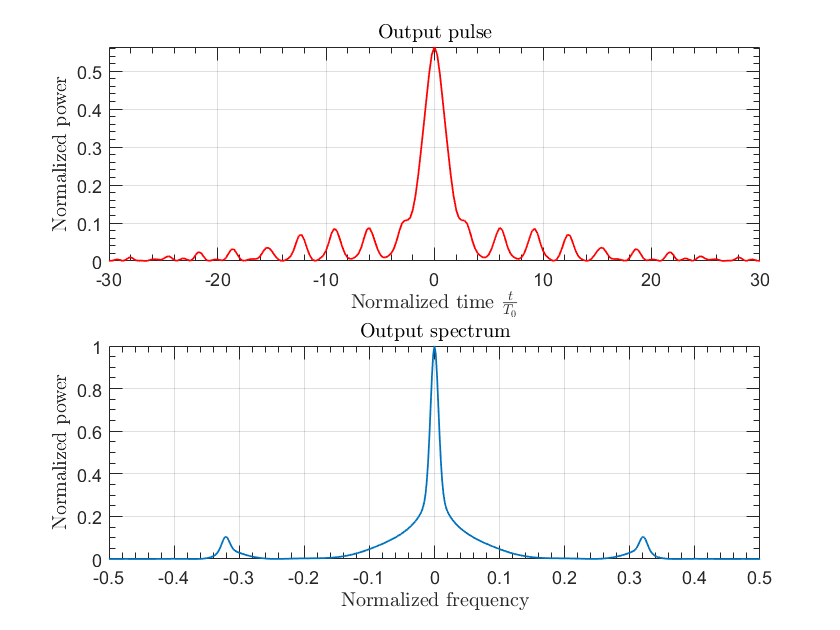


%---store dispersive phase shifts---%               
dispersion = exp(0.5i * beta2* omega.^2 *deltaz);   %phase factor
hhz = 1i*N^2*deltaz;                                %nonlinear phase factor

%----[Beginning of MAIN loop]----%
temp = uu.*exp(abs(uu).^2 .* hhz);
for n = 1:step_num
    f_temp = ifft(temp).*dispersion;
    uu = fft(f_temp);
    temp = uu.*exp(abs(uu).^2.*hhz);
end
uu = temp.*exp(abs(uu).^2 .* hhz);
%----[End of MAIN loop]----%

%---plot output pulse shape and spectrum---%
temp = fftshift(ifft(uu));            %fourier transform
spect = abs(temp).^2;                 %input spectrum
spect = spect./max(spect);            %normalized spectrum
freq = fftshift(omega)/(2*pi);        %frequency array

figure(2)
subplot(2,1,1)
plot(tau, abs(uu).^2, "LineWidth", 0.9, "Color", [1 0 0])
% legend('$J_5(q, \tau)$', 'Interpreter', 'latex')
xlabel('Normalized time $\frac{t}{T_0}$', "Interpreter", "latex")
ylabel('Normalized power', 'Interpreter',"latex")
title('Output pulse', "Interpreter","latex")
xlim([-30 30])
ylim([0 max(abs(uu).^2)])
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
         'TickLength', [0.02, 0.04], ...
         'LineWidth', 0.5);

subplot(2,1,2)
plot(freq, spect, "LineWidth", 0.9)
title('Output spectrum', "Interpreter","latex")
xlabel('Normalized frequency', "Interpreter", "latex")
ylabel('Normalized power', 'Interpreter',"latex")
xlim([-.5 .5])
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
         'TickLength', [0.02, 0.04], ...
         'LineWidth', 0.5);